# 2 DOF Cell Model in plane strain

## Data

% 
clearvars; close all; clc;
set_env;
addpath("Functions and Scripts\");
addpath("2DOF\");
load('C:\Universita\MAGISTRALE\MasterThesis\MATLAB\1DOF\res_1dof_pstrain.mat')

%

% Data --------------------------------------------------------------
epsilon1_max = 0.05;
strpstrain = "PSTRAIN";
% Symbolic variables ------------------------------------------------
% Physical properties
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f real positive

% Geometry of the capacitor
syms x l_0 l_c w_0 tp_0 xi xi_0 tf_0 dt_f dtf real positive
% t_f(x) armature distance at a certain xsi

% Physical quantities
syms Uel(x) V F C(x) 

syms epsilon_1(x) epsilon_2(x) epsilon_3(x) sigma_1(x)

## Equations

% Equations ---------------------------------------------------------
makeassumptions
% Geometry ------------------------------
dt_f(x) = simplify(solve((x/2 - tf_0 / 2) / (l_0 - l_c) == (dtf / 2) / (l_0 - l_c - (xi - xi_0)), dtf), 25)

$$dt\_f(x) = -\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-l_{c}-\xi +\xi_{0}\right)}{l_{0}-l_{c}}$$

t_f(x) = tf_0 + dt_f;
limit(t_f(x), l_c, l_0)

$$ans = \left\{ \begin{array}{cl} x & \text{ if }{\mathrm{tf}}_{0}=x\vee \xi =\xi_{0} \end{array}\right.$$



pstrain = compute_geometry2(@(x)t_f(x), strpstrain);
l_c;
l_a = pstrain.l_a

$$l\_a = l_{0}-l_{c}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}$$

w = pstrain.w

$$w = w_{0}$$

t_p = pstrain.t_p

$$t\_p = {\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)$$

A1 = pstrain.A1

$$A1 = l_{c}\,w_{0}$$

A2 = pstrain.A2

$$A2 = w_{0}\,\left(l_{0}-l_{c}+\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{8\,l_{0}-8\,l_{c}}\right)$$


C1 = pstrain.C1

$$C1 = \frac{1}{\frac{{\mathrm{tf}}_{0}}{\epsilon_{f}\,l_{c}\,w_{0}}+\frac{2\,{\mathrm{tp}}_{0}}{\epsilon_{p}\,l_{c}\,w_{0}}}$$

makeassumptions
fprintf("C1 as x -> tf_0 \n")

C1 as x -> tf_0 


simplify(limit(sstrain2(C1), x, tf_0))

$$ans = \frac{\epsilon_{f}\,\epsilon_{p}\,l_{c}\,w_{0}}{\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}}$$

fprintf("C1 as l_c -> l_0 \n")

C1 as l_c -> l_0 


simplify(limit(C1, l_c, l_0))

$$ans = \frac{\epsilon_{f}\,\epsilon_{p}\,l_{0}\,w_{0}}{\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}}$$

fprintf("C1 as l_c -> 0 \n")

C1 as l_c -> 0 


simplify(limit(C1, l_c, 0))

$$ans = 0$$


C2 = simplify(pstrain.C2)

$$C2 = -\frac{\epsilon_{f}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)\,\left(\log\left(-\left(l_{0}-l_{c}\right)\,\left(2\,\epsilon_{f}\,{\mathrm{tp}}_{0}+\epsilon_{p}\,x+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)\right)-\log\left(-\left(l_{0}-l_{c}\right)\,\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}\,\epsilon_{3}\left(x\right)\right)-\epsilon_{p}\,l_{c}\,\left({\mathrm{tf}}_{0}-x\right)\right)\right)\,\left(l_{0}-l_{c}\right)}{{\mathrm{tf}}_{0}-x}$$

makeassumptions
fprintf("C2 as x -> tf_0, l_c = l_0? \n")

C2 as x -> tf_0, l_c = l_0? 


simplify(limit(sstrain2(C2), x, tf_0))

$$ans = \frac{\epsilon_{f}\,\epsilon_{p}\,l_{0}\,w_{0}\,\left(l_{c}+\sqrt{{\left(l_{0}-l_{c}\right)}^{2}}\right)\,\left(\nu -1\right)}{\epsilon_{p}\,l_{0}\,\nu \,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,l_{c}\,\nu \,{\mathrm{tp}}_{0}+2\,\epsilon_{f}\,\nu \,{\mathrm{tp}}_{0}\,\sqrt{{\left(l_{0}-l_{c}\right)}^{2}}}$$

fprintf("C2 as l_c -> l_0 \n")

C2 as l_c -> l_0 


simplify(limit(sstrain2(C2), l_c, l_0))

$$ans = 0$$

fprintf("C2 as l_c -> l_0, x -> tf_0 \n")

C2 as l_c -> l_0, x -> tf_0 


simplify(limit(ans, x, tf_0))

$$ans = 0$$

fprintf("C2 as l_c -> 0 \n")

C2 as l_c -> 0 


simplify(limit(sstrain2(C2) , l_c, 0))

$$ans = \frac{\epsilon_{f}\,w_{0}\,\left(\log\left(-l_{0}\,\left(\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}+\frac{2\,\epsilon_{f}\,\nu \,{\mathrm{tp}}_{0}\,\left(\frac{\sqrt{{\left(\frac{{\mathrm{tf}}_{0}}{2}-\frac{x}{2}\right)}^{2}+{l_{0}}^{2}}}{l_{0}}-1\right)}{\nu -1}\right)\right)-\log\left(-l_{0}\,\left(2\,\epsilon_{f}\,{\mathrm{tp}}_{0}+\epsilon_{p}\,x+\frac{2\,\epsilon_{f}\,\nu \,{\mathrm{tp}}_{0}\,\left(\frac{\sqrt{{\left(\frac{{\mathrm{tf}}_{0}}{2}-\frac{x}{2}\right)}^{2}+{l_{0}}^{2}}}{l_{0}}-1\right)}{\nu -1}\right)\right)\right)\,\sqrt{{\left(\frac{{\mathrm{tf}}_{0}}{2}-\frac{x}{2}\right)}^{2}+{l_{0}}^{2}}}{{\mathrm{tf}}_{0}-x}$$

fprintf("C1 1 DOF\n")

C1 1 DOF


res_1dof_pstrain.C

$$ans(x) = \left\{ \begin{array}{cl} \frac{\epsilon_{f}\,\epsilon_{p}\,l_{0}\,w_{0}}{\epsilon_{p}\,{\mathrm{tf}}_{0}+2\,\epsilon_{f}\,{\mathrm{tp}}_{0}} & \text{ if }x\leq {\mathrm{tf}}_{0}+\frac{1}{10000000000}\\ \frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-\frac{2\,\epsilon_{f}\,l_{0}\,\nu \,{\mathrm{tp}}_{0}\,\left(\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}-1\right)}{\nu -1}\right)\,\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}}{{\mathrm{tf}}_{0}-x}-\frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(\epsilon_{p}\,l_{0}\,\left({\mathrm{tf}}_{0}-x\right)-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-\frac{2\,\epsilon_{f}\,l_{0}\,\nu \,{\mathrm{tp}}_{0}\,\left(\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}-1\right)}{\nu -1}\right)\,\sqrt{\frac{{\left({\mathrm{tf}}_{0}-x\right)}^{2}}{4\,{l_{0}}^{2}}+1}}{{\mathrm{tf}}_{0}-x} & \text{ if }{\mathrm{tf}}_{0}+\frac{1}{10000000000}<x \end{array}\right.$$

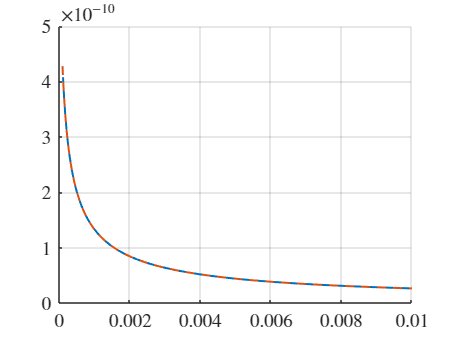

myfig(1, ""); hold on; grid on;
fplot(x,sdata2(simplify(limit(sstrain2(C2) , l_c, 0))), [double(sdata2(tf_0)) , 10e-3], 'LineWidth', 1.5)
fplot(x,sdata2(res_1dof_pstrain.C), [double(sdata2(tf_0)) , 10e-3], '--', 'LineWidth', 1.5)


% Range limit
x_min = tf_0

$$x\_min = {\mathrm{tf}}_{0}$$

x_max = rhs(isolate(sstrain2(epsilon_1(x)) == epsilon1_max, x))

$$x\_max = {\mathrm{tf}}_{0}+\frac{\sqrt{41}\,l_{0}}{10}$$

## Capacitance

% Total capacitance +++++++++++++++++++++++++++++++++++++++++++++++++
C(x) = sstrain2(C1)

$$C(x) = \frac{1}{\frac{{\mathrm{tf}}_{0}}{\epsilon_{f}\,l_{c}\,w_{0}}+\frac{2\,{\mathrm{tp}}_{0}}{\epsilon_{p}\,l_{c}\,w_{0}}}$$


% Min capacitance
Cmin = vpa(sdata2(limit(C, x, x_max)),4)

$$Cmin = 1.71e-8\,l_{c}$$


% Max capacitance
Cmax = vpa(sdata2(limit(sstrain2(C, strpstrain), x, tf_0)),4)

$$Cmax = 1.71e-8\,l_{c}$$

## Elastic energy

Uel(x) = simplify(vpa(sdata2(2 * (1 / 2 * (sigma_1 * epsilon_1) * w * t_p * (l_c + l_a)), strpstrain), 4), 100)

$$Uel(x) = -\frac{171703.296703338623046875\,{\left(x-0.000099999999999988986587595718447119\right)}^{4}\,\left(\frac{2.1428571428550640121102333068848\,{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{l_{c}-0.024999999999977262632455676794052}+1.0\right)\,\left(\frac{{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{8.0\,l_{c}-0.19999999999981810105964541435242}-0.024999999999977262632455676794052\right)}{{\left(l_{c}-0.024999999999977262632455676794052\right)}^{2}}$$

diff(Uel(x),x) - V^2 /2 * diff(sdata2(C), x) == F

$$ans(x) = -\frac{367935.63579251153341215241354689\,{\left(x-0.000099999999999988986587595718447119\right)}^{4}\,\left(2.0\,x-0.00019999999999997797317519143689424\right)\,\left(\frac{{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{8.0\,l_{c}-0.19999999999981810105964541435242}-0.024999999999977262632455676794052\right)}{{\left(l_{c}-0.024999999999977262632455676794052\right)}^{3}}-\frac{686813.1868133544921875\,{\left(x-0.000099999999999988986587595718447119\right)}^{3}\,\left(\frac{2.1428571428550640121102333068848\,{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{l_{c}-0.024999999999977262632455676794052}+1.0\right)\,\left(\frac{{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{8.0\,l_{c}-0.19999999999981810105964541435242}-0.024999999999977262632455676794052\right)}{{\left(l_{c}-0.024999999999977262632455676794052\right)}^{2}}-\frac{171703.296703338623046875\,{\left(x-0.000099999999999988986587595718447119\right)}^{4}\,\left(\frac{2.1428571428550640121102333068848\,{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{l_{c}-0.024999999999977262632455676794052}+1.0\right)\,\left(2.0\,x-0.00019999999999997797317519143689424\right)}{{\left(l_{c}-0.024999999999977262632455676794052\right)}^{2}\,\left(8.0\,l_{c}-0.19999999999981810105964541435242\right)}=F$$

eq2 = diff(Uel,l_c) - V^2 /2 * diff(sdata2(C), l_c) == 0

$$eq2(x) = \frac{367935.63579251153341215241354689\,{\left(x-0.000099999999999988986587595718447119\right)}^{6}\,\left(\frac{{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{8.0\,l_{c}-0.19999999999981810105964541435242}-0.024999999999977262632455676794052\right)}{{\left(l_{c}-0.024999999999977262632455676794052\right)}^{4}}-\frac{4304160690449694361745028943077125\,V^{2}}{503299072649607880422191459995710467866624}+\frac{1373626.373626708984375\,{\left(x-0.000099999999999988986587595718447119\right)}^{6}\,\left(\frac{2.1428571428550640121102333068848\,{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{l_{c}-0.024999999999977262632455676794052}+1.0\right)}{{\left(l_{c}-0.024999999999977262632455676794052\right)}^{2}\,{\left(8.0\,l_{c}-0.19999999999981810105964541435242\right)}^{2}}+\frac{343406.59340667724609375\,{\left(x-0.000099999999999988986587595718447119\right)}^{4}\,\left(\frac{2.1428571428550640121102333068848\,{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{l_{c}-0.024999999999977262632455676794052}+1.0\right)\,\left(\frac{{\left(x-0.000099999999999988986587595718447119\right)}^{2}}{8.0\,l_{c}-0.19999999999981810105964541435242}-0.024999999999977262632455676794052\right)}{{\left(l_{c}-0.024999999999977262632455676794052\right)}^{3}}=0$$



% % Plot x - C(x)
% myfig(1,"x - C(x)");
% hold on
% fplot(x, sdata(C(x), 1), [x_min, sdata(x_max)], 'LineWidth', 2)
% xline(sdata(x_max), "--g", "x_{MAX}",'LabelOrientation','horizontal', 'FontWeight','bold')
% hold off
% title("x - C(x)")
% xlabel("x [m]")
% ylabel("C(x) [F]")
% 

## Max voltage

% % Max voltage
% % Vmax(x) = A / C * min(epsilon_p * EBD_p, epsilon_f * EBD_f)
% Vmax(x) = 2 * t_p / epsilon_p * min(epsilon_p * EBD_p, epsilon_f * EBD_f)
% 
% % Plot x - Vmax(x)
% myfig(2,"x - Vmax(x)");
% fplot(x, sdata(Vmax(x), 1), [x_min, sdata(x_max)], 'LineWidth', 2)
% title("$x - V_{max}(x)$")
% xlabel("x [m]")
% ylabel("$V_{max}$(x) [V]")
% 

## Force

% % Force
% Uel(x) = 2 * sdata(1 / 2 * (sigma_1 * epsilon_1) * w * t_p * l, 1)
% 
% F(x,V) = simplify(diff(Uel, x) - V^2 / 2 * diff(sdata(C, 1), x), 500)
% 
% % Min and max force for V = 0 and V = Vmax
% FVmin = vpa(F(x, 0), 4);
% FVmax= vpa(F(x, sdata(Vmax, 1)), 4);

% % Plot x - F(x)
% xtmp = 2e-3:1e-4:2.5e-3;
% [~, idx] = min(real(subs(FVmax, x, xtmp)));
% xstart = xtmp(idx)
% 
% x_range = x_min:1e-4:sdata(x_max);
% FVmin_vec = subs(FVmin,x_range);
% FVmax_vec = real(subs(FVmax,x_range));
% Uel_Fx = double(trapz(x_range, FVmax_vec) - trapz(x_range, FVmin_vec))
% 
% myfig(3,"x - F(x)")
% hold on
% fplot(x, FVmin, [0, 1.2 * sdata(x_max)], 'LineWidth', 1.5)
% fplot(x, FVmax, [0, 1.2 * sdata(x_max)], '--', 'LineWidth', 1.5)
% xline(sdata(x_max), "--g", "x_{MAX}",'LabelOrientation','horizontal', 'FontName', 'times new roman', 'FontWeight','bold')
% xline(sdata(xstart), "--g", "x_{START}",'LabelOrientation','horizontal', 'FontName', 'times new roman', 'FontWeight','bold')
% hold off
% legend(["$V_{min}$", "$V_{max}$"], "Location", "north")
% title("x - F(x)")
% xlabel("x [m]")
% ylabel("F(x) [N]")
% 

## Q - V

% % Plot Q - V
% C_vec = subs(sdata(C, 1), x_range);
% Vmax_vec = subs(sdata(Vmax, 1), x_range);
% Q_vec = C_vec .* Vmax_vec;
% 
% [V_maxstr_min, idx] = min(Q_vec ./ Cmin);
% x_min_maxstr = x_range(idx);
% 
% [V_minstr_min, idx] = min(Q_vec ./ Cmax);
% x_min_minstr = x_range(idx);

% myfig(4,"Q - V"); clf
% hold on
% plot(Q_vec, Vmax_vec, 'DisplayName', "Voltage breakdown", "LineWidth", 1.5)
% plot(Q_vec, Q_vec ./ Cmax, 'DisplayName', "Min. stretch", "LineWidth", 1.5)
% plot(Q_vec, Q_vec ./ Cmin, 'DisplayName', "Max. stretch", "LineWidth", 1.5)
% legend('Location','best')
% xlabel("Q [A]")
% ylabel("V [V]")
% % ylim([0,max(Vmax_vec)])
% title("Q - V")
% hold off
% 






















